clc, clearvars;

defaultSimLocation = 'D:\Creo_Simulations';

[creoResultsFile,creoResultsLocation] = uigetfile_extended('xlsx', defaultSimLocation);
fluxTable = readtable(fullfile(creoResultsLocation, creoResultsFile), "FileType","spreadsheet");

[creoResultsFile,~] = uigetfile_extended('xlsx', defaultSimLocation);
l1TempTable = readtable(fullfile(creoResultsLocation, creoResultsFile), "FileType","spreadsheet");

[creoResultsFile,~] = uigetfile_extended('xlsx', defaultSimLocation);
l2TempTable = readtable(fullfile(creoResultsLocation, creoResultsFile), "FileType","spreadsheet");

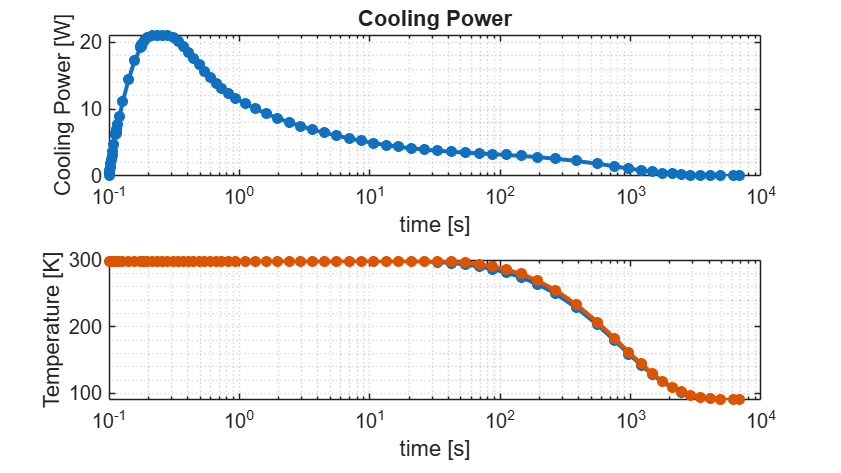

figure('Units','normalized', 'Position',[0 0 0.85 0.85])
ax = [];

ax(1) = subplot(211);
semilogx(fluxTable.Time, fluxTable.Heat_flux *52.9e-6,'-o' ,'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0);
ylabel('Cooling Power [W]');
xlabel('time [s]');
title('Cooling Power');
grid minor
ax(2) = subplot(212);
semilogx(l1TempTable.Time, l1TempTable.temp_at_point_L1_S1_VERTEX + 273.15,'-o' ,...
         'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0,...
         'DisplayName','T_{L1}'); hold on;
semilogx(l2TempTable.Time, l2TempTable.temp_at_point_L2_S1_VERTEX + 273.15,'-o' ,...
         'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0,...
         'DisplayName','T_{L2}');
ylabel('Temperature [K]');
xlabel('time [s]');
grid minor

set(ax, 'FontSize', 15);